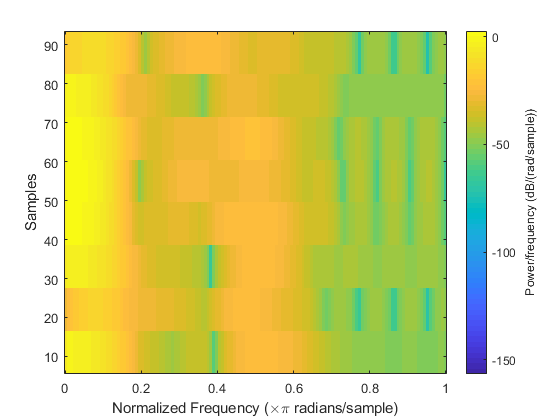

[x,fs] = audioread('4_1.wav');
%sound(x,fs); 
x_L = x(:,1);
x_R = x(:,2);
x_ambient_L = x_L - x_R;
x_ambient_R = x_R - x_L;
%sound(x_ambient,fs);

y_l=delayseq(x_ambient_L,50/fs,fs);
y_all_l = x_ambient_L + y_l;

y_r=delayseq(x_ambient_R,50/fs,fs);
y_all_r = x_ambient_R + y_r;
%pause(11)
 %sound(y_all,fs);
x_new_L = y_all_l+x_R;
x_new_R = y_all_r+x_L;
x_new = [x_new_L,x_new_R];
%pause(15)
%sound(x_new,fs);
%audiowrite('4_1_50s.wav',x_new,fs);

%spectrogram(x_L(1:100));

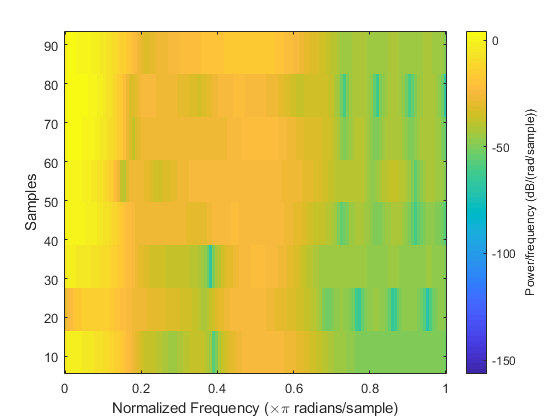

%figure;
%spectrogram(x_new_L(1:100));